M = readmatrix('natural_freq_meas.txt');

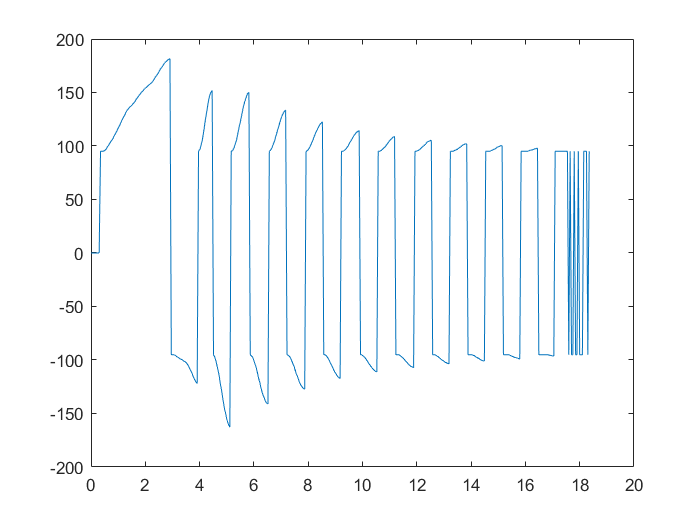

time = linspace(0,18.350,367);%M(:,1)-M(1,1); every 50 ms in s
angle = M(:,2).*(180/pi); %% convert to angles/s from rads/s

plot(time,angle);

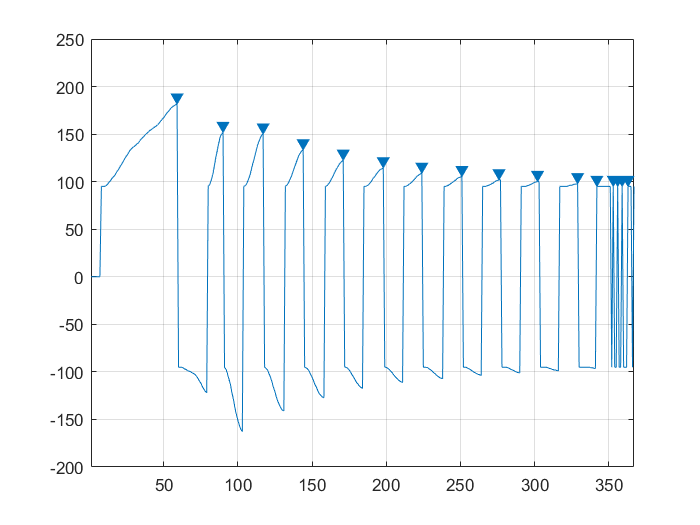

findpeaks(angle); % pretty plot :)

[pks,locs] = findpeaks(angle);

pk_times = locs;
for i = 1:length(locs)
    pk_times(i,1) = time(locs(i,1));
end
pk_times

pk_times =     2.9079
    4.4622
    5.8158
    7.1695
    8.5232
    9.8769
   11.1805
   12.5342
   13.7876
   15.0911


tao = mean(diff(pk_times(1:end-10)))

tao = 1.3938

omega_n = 2*pi*(1./tao)

omega_n = 4.5080



% calculate natural frequency
g = 9.8; % m/s^2

l = g/(omega_n^2) % m

l = 0.4822

l_cm = l*100

l_cm = 48.2243

l_in = l*39.3701

l_in = 18.9860